# Data analysis of Bilbasen data set

clear;

## Load data set

opts = detectImportOptions("bilbasen_scrape.csv");
source = readtable("bilbasen_scrape.csv", opts);
preview("bilbasen_scrape.csv", opts)

ans = 8×18 table
       Make            Model                    Configuration                 Rating         Price         Registered      Kilometers                Fuel                    Consumption                Tax                  Power           Transmission     TowCapacity        PriceNew            Trunk          Width         Length        Height  
    ___________    _____________    ______________________________________    ______    _______________    ___________    _____________    _________________________    ____________________

Some fiddling to learn syntax

source(1:3, 1:6)

ans = 3×6 table
       Make          Model                   Configuration                 Rating         Price         Registered
    ___________    __________    ______________________________________    ______    _______________    __________

    {'Ford'   }    {'Kuga'  }    {'2,5 PHEV Vignale CVT 5d'           }     4.4      {'226.300 kr.'}    {'7/2020'}
    {'Peugeot'}    {'3008'  }    {'1,6 Hybrid First Selection EAT8 5d'}     4.4      {'199.900 kr.'}    {'2/2021'}
    {'VW'     }    {'Passat'}    {'1,4 GTE Variant DSG 5d'            }     4.3      {'239.000 kr.'}    {'5/2020'}


source(1:6, "Model")

ans = 6×1 table
        Model    
    _____________

    {'Kuga'     }
    {'3008'     }
    {'Passat'   }
    {'Kuga'     }
    {'Golf VIII'}
    {'Octavia'  }


source.Model(1:6)

ans = 6×1 cell array
    {'Kuga'     }
    {'3008'     }
    {'Passat'   }
    {'Kuga'     }
    {'Golf VIII'}
    {'Octavia'  }


source.Properties.VariableNames

ans = 1×18 cell array
    {'Make'}    {'Model'}    {'Configuration'}    {'Rating'}    {'Price'}    {'Registered'}    {'Kilometers'}    {'Fuel'}    {'Consumption'}    {'Tax'}    {'Power'}    {'Transmission'}    {'TowCapacity'}    {'PriceNew'}    {'Trunk'}    {'Width'}    {'Length'}    {'Height'}


source.Properties.VariableTypes

ans = 1×18 string array
    "cell"    "cell"    "cell"    "double"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"


## Check for empty cells in selected columns

% Get column as cell matrix (height) or table (b)
height = source.("Height");
b = source(:, "Height");

% Convert to string and look for non-empty strings
indexes_of_non_empty_cells = find(string(height) ~= "")

indexes_of_non_empty_cells =      1
     2
     3
     4
     5
     6
     7
     9
    10
    12


height = height(indexes_of_non_empty_cells)

height = 1118×1 cell array
    {'166 cm'}
    {'162 cm'}
    {'152 cm'}
    {'166 cm'}
    {'146 cm'}
    {'149 cm'}
    {'166 cm'}
    {'148 cm'}
    {'151 cm'}
    {'166 cm'}
    {'166 cm'}
    {'146 cm'}
    {'166 cm'}
    {'146 cm'}
    {'152 cm'}
    {'146 cm'}
    {'146 cm'}
    {'170 cm'}
    {'166 cm'}
    {'161 cm'}
    {'144 cm'}
    {'147 cm'}
    {'166 cm'}
    {'166 cm'}
    {'166 cm'}
    {'166 cm'}
    {'154 cm'}
    {'146 cm'}
    {'146 cm'}
    {'146 cm'}


## Remove characters from cells and convert to number

The height column content is formatted like '168 cm'. Removing the last three characters allows us to convert to doubles.

height = double(erase(string(height), " cm"))

height =    166
   162
   152
   166
   146
   149
   166
   148
   151
   166


Check for and remove 'NaN' values

height = height(find(not(isnan(height))))

height =    166
   162
   152
   166
   146
   149
   166
   148
   151
   166


Column is now cleaned.

min(height)

ans = 139

max(height)

ans = 172

mean(height)

ans = 154.3217

## Add a column with age of car

This can be calculated from the registration month of the car. MATLABs datetime type is useful for this metric.

registered = string(source.("Registered"));
registered = datetime(registered, "InputFormat","MM/yyyy");
source.Age = calmonths(between(registered, datetime("today"))) / 12;

## Clean up km column and PriceNew column

km = string(source.Kilometers);
km = double(erase(km,[" km", "."]));
source.("Kilometers") = km;

price = string(source.Price);
price = double(erase(price, [" kr.", "."]));
source.Price = price;

pricenew = string(source.PriceNew);
pricenew = double(erase(pricenew, [" kr.", "."]));
source.PriceNew = pricenew;

## Find every car less than 50.000 kr

Clean price column

df = source;
price = df.("Price");
% Convert to string and look for non-empty strings
indexes_of_non_empty_cells = find(string(price) ~= "");
df = df(indexes_of_non_empty_cells, :);

price = erase(string(price), " kr.");
price = double(erase(string(price), "."));
df = df(find(not(isnan(price))),:);

Cleaned, ready for logical indexing.

lessthan50k = df(price <= 50000, :)

lessthan50k = 59×19 table
       Make               Model                          Configuration                  Rating    Price    Registered     Kilometers       Fuel           Consumption                Tax                  Power          Transmission    TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ____________________    _________________________________________    ______    _____    ___________    __________    __________    ____________________    

## Find every car in tax bracket less than 1860 kr/year

Remove characters and convert to numbers

tax = lessthan50k.("Tax");
tax = erase(string(tax), " kr. / år");
tax = erase(string(tax), ".");
tax = double(tax);
lessthan50k.Tax = tax

lessthan50k = 59×19 table
       Make               Model                          Configuration                  Rating    Price    Registered     Kilometers       Fuel           Consumption         Tax           Power          Transmission    TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ____________________    _________________________________________    ______    _____    ___________    __________    __________    ____________________    ____

lessthan50k = lessthan50k(lessthan50k.("Tax") < 1860, :)

lessthan50k = 31×19 table
       Make            Model                       Configuration                  Rating    Price    Registered     Kilometers       Fuel              Consumption           Tax           Power           Transmission     TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ______________    _________________________________________    ______    _____    ___________    __________    __________    _________________________    ____

## Find every car that has a fuel economy of >28km/l

Remove characters and convert to numbers

consumption = lessthan50k.("Consumption");
consumption = erase(string(consumption), "(NEDC) ");
consumption = erase(string(consumption), " km/l");
consumption = double(replace(string(consumption), ",", "."))

consumption =    26.3000
   33.3000
   33.3000
   33.3000
   26.3000
   30.3000
   28.6000
   31.3000
   33.3000
   31.3000



lessthan50k.Consumption = consumption;
lessthan50k = lessthan50k(lessthan50k.("Consumption") > 28, :)

lessthan50k = 26×19 table
       Make            Model                        Configuration                    Rating    Price    Registered     Kilometers       Fuel       Consumption    Tax           Power          Transmission    TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ______________    ____________________________________________    ______    _____    ___________    __________    __________    ___________    ____    ________

## Sort by PriceNew

The more expensive-as-new priced cars should be more desirable

pricenew = lessthan50k.("PriceNew");
pricenew = double(erase(string(pricenew), [" kr.", "."]));
lessthan50k.("PriceNew") = pricenew;
sorted_price_new = sortrows(lessthan50k, "PriceNew", 'descend');

## Get unique cars

[C,ia] = unique(lessthan50k.Configuration);
unique_cars = lessthan50k(ia, :)

unique_cars = 14×19 table
       Make            Model                        Configuration                    Rating    Price    Registered     Kilometers       Fuel       Consumption    Tax           Power          Transmission    TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ______________    ____________________________________________    ______    _____    ___________    __________    __________    ___________    ____    ________

## Manual selection

At this point, I would like to narrow down the scope of models for further analysis. **Opel Corsa **is dropped for its weak engine and small size. The **Citroën C3** is deemed too small as well, and the **Volvo V40** is dropped as it is too long, and predumably more expensive to repair in case of issues.

c4indexes = string(source.("Model")) == 'C4';
c4 = source(c4indexes, :)

c4 = 24×19 table
       Make        Model                  Configuration                  Rating    Price    Registered    Kilometers       Fuel           Consumption                Tax                  Power           Transmission     TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ______    ________________________________________    ______    _____    __________    __________    __________    ____________________    __________________    


p308indexes = string(source.("Model")) == '308';
p308 = source(p308indexes, :)

p308 = 85×19 table
       Make         Model                  Configuration                  Rating      Price      Registered     Kilometers       Fuel           Consumption                Tax                  Power           Transmission     TowCapacity      PriceNew         Trunk          Width         Length        Height       Age  
    ___________    _______    ________________________________________    ______    _________    ___________    __________    __________    ____________________    ____________

The Renault Megane is listed as Megane III. To make this analysis consistent, I want to consider all Megane models.

meganeindexes = contains(string(source.("Model")), "Megane");
megane = source(meganeindexes, :)

megane = 31×19 table
       Make            Model                           Configuration                       Rating      Price      Registered     Kilometers       Fuel           Consumption                Tax                  Power           Transmission     TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ______________    __________________________________________________    ______    _________    ___________    __________    __________    ____________________

## Calculate mean new price values

new price values are missing for some entries. We either scrap those value for modelling, or give them an average value. As the dataset is not that large, I prefer to give them an average value to keep the associated data points for that entry. A better way would be to find an entry with a matching configuration, and use the price_new from there.

mean_price_new_c4 = mean(c4.PriceNew, "omitnan")

mean_price_new_c4 = 2.2218e+05

i = find(isnan(c4.PriceNew));
c4.PriceNew(i) = mean_price_new_c4;

mean_price_new_p308 = mean(p308.PriceNew, "omitnan")

mean_price_new_p308 = 2.7036e+05

i = find(isnan(p308.PriceNew));
p308.PriceNew(i) = mean_price_new_p308;

mean_price_new_megane = mean(megane.PriceNew, "omitnan")

mean_price_new_megane = 2.6142e+05

i = find(isnan(megane.PriceNew));
megane.PriceNew(i) = mean_price_new_megane;


## Fitted models

[c4fitted, c4gof] = fitcar(c4)

c4fitted =      General model:
     c4fitted(km,age) = exp(b*km + c*age)
     Coefficients (with 95% confidence bounds):
       b =  -3.773e-06  (-5.022e-06, -2.523e-06)
       c =    -0.06236  (-0.08362, -0.0411)

c4gof = struct with fields:
           sse: 0.0485
       rsquare: 0.7374
           dfe: 22
    adjrsquare: 0.7254
          rmse: 0.0470



[p308fitted, p308gof] = fitcar(p308)

p308fitted =      General model:
     p308fitted(km,age) = exp(b*km + c*age)
     Coefficients (with 95% confidence bounds):
       b =  -3.275e-06  (-3.946e-06, -2.605e-06)
       c =    -0.07268  (-0.08587, -0.05949)

p308gof = struct with fields:
           sse: 0.1582
       rsquare: 0.7148
           dfe: 83
    adjrsquare: 0.7114
          rmse: 0.0437



[meganefitted, meganegof] = fitcar(megane)

meganefitted =      General model:
     meganefitted(km,age) = exp(b*km + c*age)
     Coefficients (with 95% confidence bounds):
       b =  -2.595e-06  (-4.128e-06, -1.062e-06)
       c =    -0.07607  (-0.1025, -0.04965)

meganegof = struct with fields:
           sse: 0.0982
       rsquare: 0.6583
           dfe: 29
    adjrsquare: 0.6465
          rmse: 0.0582



x_age = 0:25

x_age =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


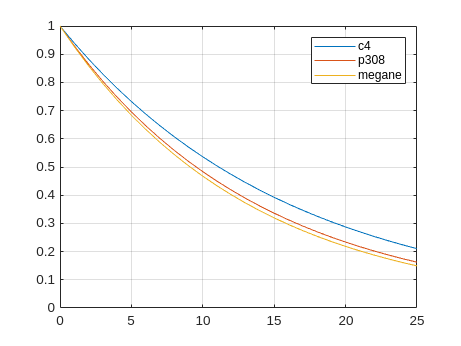

ys = [exp(c4fitted.c * x_age); exp(p308fitted.c * x_age); exp(meganefitted.c * x_age)];
p1 = plot(x_age,ys);
legend("c4", "p308", "megane")
ylim([0, 1])
grid on

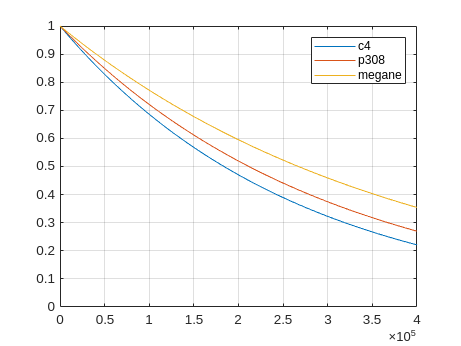


x_km = 0:400000;
ys = [exp(c4fitted.b * x_km); exp(p308fitted.b * x_km); exp(meganefitted.b * x_km)];
p1 = plot(x_km,ys);
legend("c4", "p308", "megane")
ylim([0, 1])
grid on

## Find best deal

%valueofdeal
c4.vod = c4.PriceNew .* exp(c4fitted.b * c4.Kilometers + c4fitted.c * c4.Age) - c4.Price;

